# Math 244: MATLAB Assignment 4

### Name: 

### RUID:  

### Date: 

clear;
clc;

## 1. 

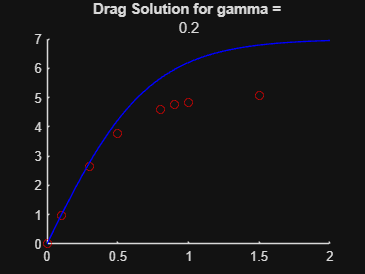

tGiven = [0, 0.1, 0.3, 0.5, 0.8, 0.9, 1.0, 1.5];
yGiven = [0, 0.96, 2.66, 3.76, 4.59, 4.77, 4.83, 5.06];
gamma = 0.2;
Tf = 2;
[t,v] = dragSolution(gamma, Tf);
% Guess a value of gamma and find the solution


figure();
hold on;
plot(tGiven, yGiven, 'ro');
title('Drag Solution for gamma = ', num2str(gamma));
plot(t, v, 'b');
% Plot the solution for your choice of gamma

hold off;

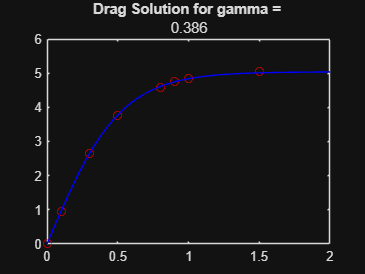

% Do it a second time
gamma = 0.386;
[t,v] = dragSolution(gamma, Tf);
figure();
plot(tGiven, yGiven, 'ro');
title('Drag Solution for gamma = ', num2str(gamma));
hold on;
plot(t, v, 'b');
hold off;

The curve tapers off at a greater value if gamma is smaller, and the opposite happens when gamma is larger.

## 2. 

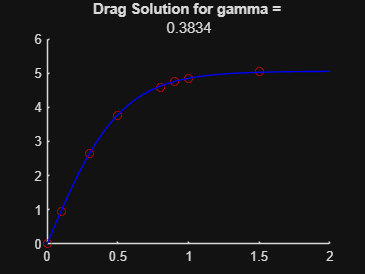

% Find the optimal gamma and the solution with that gamma.
optGam = dragOptimization(tGiven,yGiven);
[t,v] = dragSolution(optGam, Tf);

figure();
hold on;
plot(tGiven, yGiven, 'ro');
plot(t, v, 'b');
title('Drag Solution for gamma = ', num2str(optGam));
% Plot the optimal solution

hold off;

## 3. 

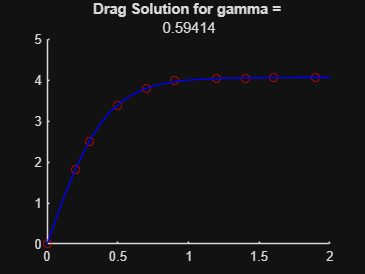

tData = [0, 0.2, 0.3, 0.5, 0.7, 0.9, 1.2, 1.4, 1.6, 1.9];
vData = [0, 1.81, 2.51, 3.38, 3.79,  4.00, 4.03, 4.04, 4.06, 4.05];
% Use optimization method to find the value of gamma. 
optGam = dragOptimization(tData,vData);
[t,v] = dragSolution(optGam, Tf);

figure();
hold on;
plot(tData, vData, 'ro');
plot(t, v, 'b');
title('Drag Solution for gamma = ', num2str(optGam));

Object one was dropped.

## 4. 

tData = [0, 1, 3, 5, 8, 12, 15, 21];
yData = [50, 64, 104, 142, 174, 186, 188, 188];



% Guess some parameters
a = 2

a = 2

K = -0.1

K = -0.1000

rho = -50

rho = -50

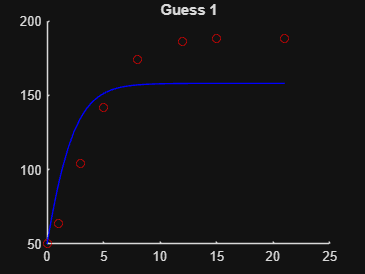

y0 = 50;
Tf = 21;
[t,y] = harvestingSolution(a, K, rho, y0, Tf);



% Plot the solution for your choice of coefficients
figure();
hold on;
plot(tData, yData, 'ro');
plot(t, y, 'b');
title('Guess 1');
hold off;

% Do it a second time


figure();
hold on;
plot(tData, yData, 'ro');

% Plot the solution for your choice of coefficients
a = 0.7;

a = 0.7000

K = -40;

K = -40

rho = -30;

rho = -30

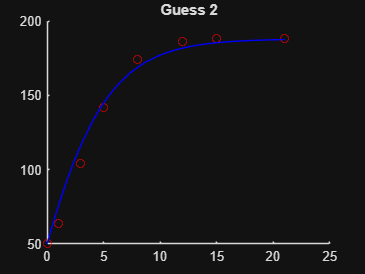

y0 = 50;
Tf = 21;
[t,y] = harvestingSolution(a, K, rho, y0, Tf);
plot(t, y, 'b');
title('Guess 2');
hold off;

## 5.

% Find the optimal coefficients and the solution with them

optParam = harvestingOptimization(tData, yData, y0);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


a = optParam(1)

a = 2.8208

K = optParam(2)

K = 204.8362

rho = optParam(3)

rho = 8.8669

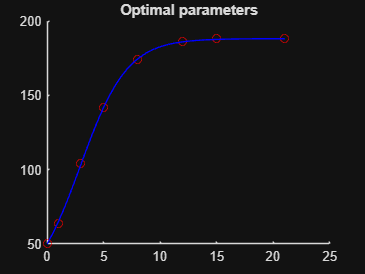

[t1,y1] = harvestingSolution(a, K, rho, y0, Tf);


% Plot the optimal solution
figure();
hold on;
plot(tData, yData, 'ro');
plot(t1, y1, 'b');
title('Optimal parameters');
hold off;

function [t,v] = dragSolution(gamma, Tf)
f = @(t,v) 9.8 - gamma.*v.^2;
[t,v] = ode45(f, [0, Tf], 0);
end

function [v] = dragSolutionVals(gamma, tVals)
f = @(t,v) 9.8 - gamma.*v.^2;
sol = ode45(f, [0, max(tVals)], 0);
v = deval(sol, tVals);
end

function optGam = dragOptimization(tVals, vVals)
testVals = @(gamma) dragSolutionVals(gamma, tVals);
testError = @(gamma) sum((testVals(gamma) - vVals).^2);
optGam = fminbnd(@(a) testError(a), 0, 1);
end

function [t,y] = harvestingSolution(a, K, rho, y0, Tf)
f = @(t,y) a.*y.*(K - y)/10^3 - rho;
[t,y] = ode45(f, [0, Tf], y0);
end

function [y] = harvestingSolutionVals(a, K, rho, y0, tVals)
f = @(t,y) a.*y.*(K - y)/10^3 - rho;
sol = ode45(f, [0, max(tVals)], y0);
y = deval(sol, tVals);
end

function optParam = harvestingOptimization(tVals, yVals, y0)
testVals = @(a, K, rho) harvestingSolutionVals(a, K, rho, y0, tVals);
testError = @(a, K, rho) sum((testVals(a, K, rho) - yVals).^2);
optParam = fmincon(@(x) testError(x(1), x(2), x(3)),[1; 300; 10],...
    [], [], [],[], [1;100;0], [5; 1000; 20]);
end


